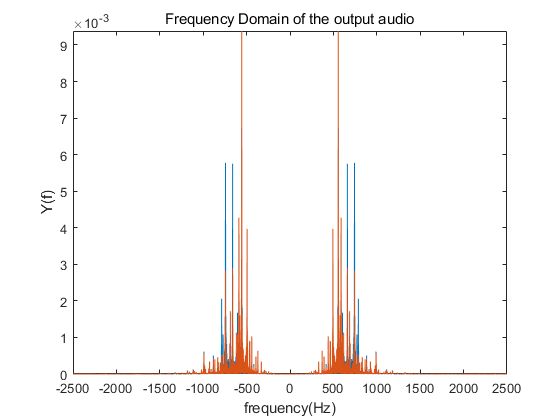

clc;clear;close all;clear sound;

[raw,fs]=audioread("magnet.mp3"); % read audio
audio=raw(fs*60+1:fs*120,:); % intercept from 1min to 2min
fil={3,[500/(fs/2),800/(fs/2)],"bandpass"}; % user select filter!!!
[b,a]=butter(fil{1},fil{2},fil{3}); % design filter
out=filter(b,a,audio); % apply filter

% plot
N=fs*60;
Y=fftshift(fft(out))/N;
f=(-N/2:N/2-1)*fs/N;
plot(f,abs(Y));
axis([-2500 2500 0 inf]);
title("Frequency Domain of the output audio");
xlabel("frequency(Hz)");
ylabel("Y(f)")

sound(out,fs);